# EFMouse: 4 x Back with craniotomy montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 4 x Back with craniotomy montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2025). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The GetDP finite element method (FEM) solver (v 3.5.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2025) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver GetDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '4xBack_craniotomy';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy'; % Results and the object (4xBack_craniotomy.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o

Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

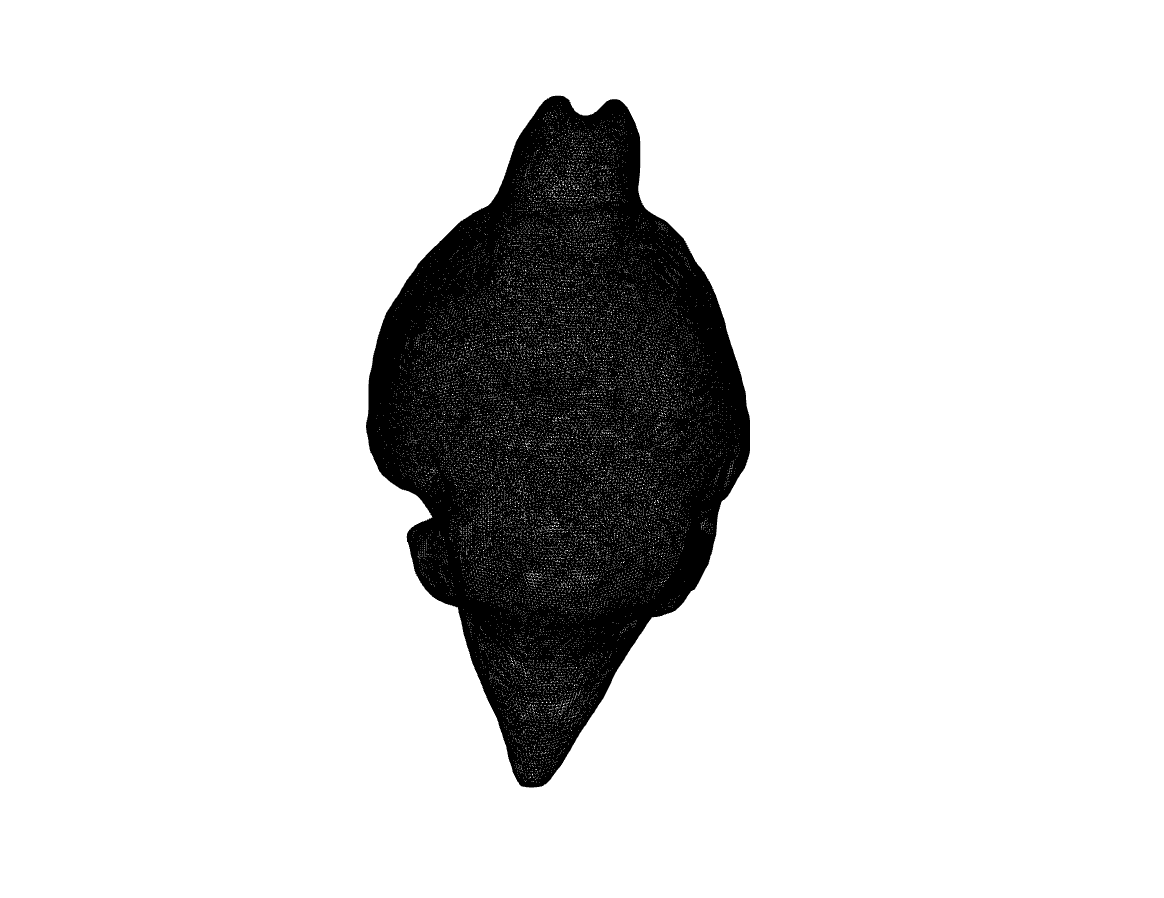

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 4 x Back center-surround stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anterior",current = 0.05,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = 0.05,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lateral",current = 0.05,type="surface",shape="circle",center= [-6,27.5,4],radius=0.6, thickness=1);
o.addElectrode(tag = "Medial",current = 0.05,type="surface",shape="circle",center= [-1,27.5,6],radius=0.6, thickness=1);

o.addElectrode(tag = "Cathode",current = -0.2,type="surface",shape="rectangle",center=[-1,-12,10],length=15,width=15,thickness=1);

Add a craniotomy between the stimulation electrodes. Select the material replacing the space where skin and bone were removed. Here, we simulate a dry craniotomy where only air flows into the space left by the removed skin and bone.

o.addCraniotomy(tag = "left",center=[-3.5,27.5,6],radius=1.5,material=["air","air"]);

To update the model with the electrodes, we run the pipeline to Stage.MESH. We can set `show=true `to visualize the electrodes and the craniotomy.

Compute stage MESH
EF Mouse Model (label: 4xBack_craniotomy) in directory /Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy (stage=INIT).
-Meshing 5 electrodes-
Closest skin node is 0.7 away from the Anterior electrode target position.
Closest skin node is 0.1 away from the Posterior electrode target position.
Closest skin node is 0.6 away from the Lateral electrode target position.
Closest skin node is 0.3 away from the Medial electrode target position.
Closest skin node is 0.5 away from the Cathode electrode target position.
Found  tet #2891752 at a distance of 0.46 from the target (label : skin)
Replacing skin with air 
Replacing bone with air 


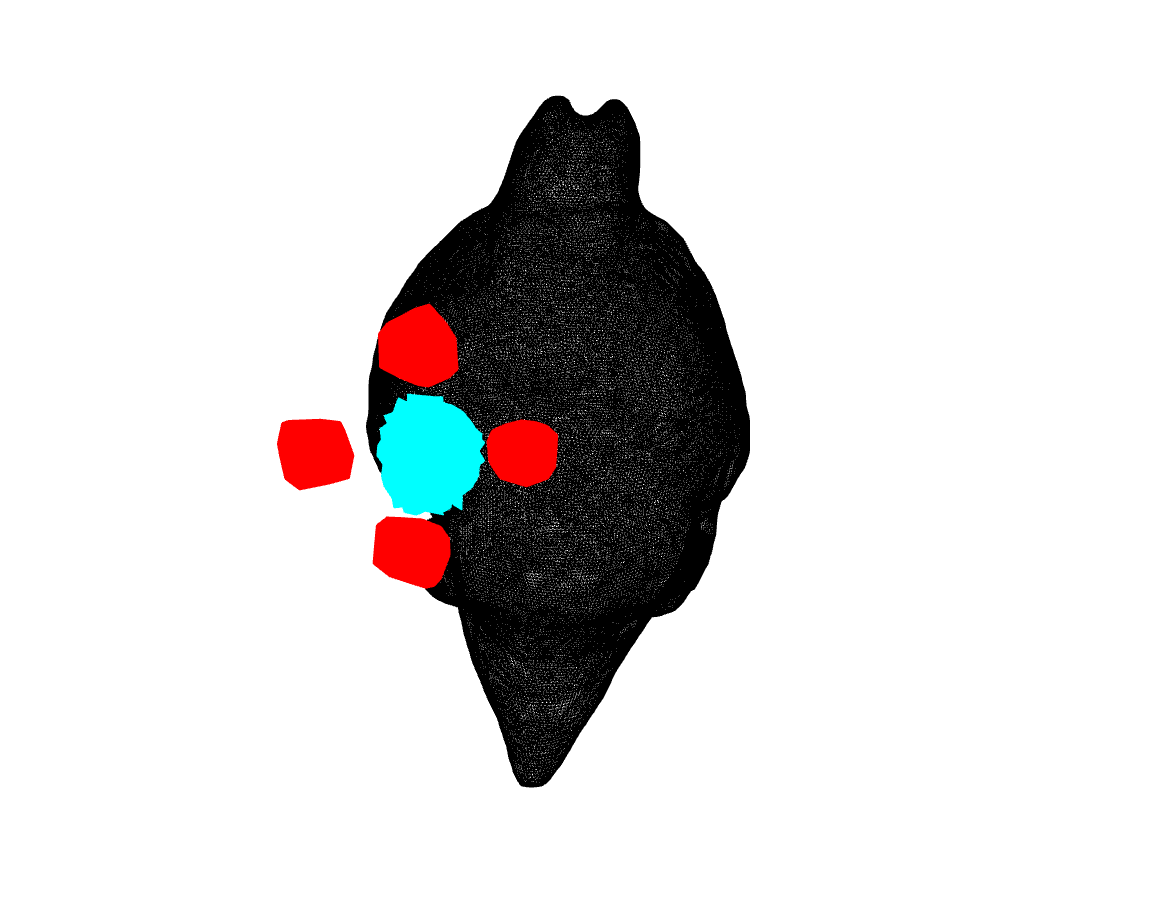

Stage MESH complete - 9.8028 seconds 


o.run(targetStage=Stage.MESH,show=true)

We can also use `plotMesh() `with skin tissue to visualize the return electrode in the back. We can also adjust the y axis dimensions to visualize the whole body.

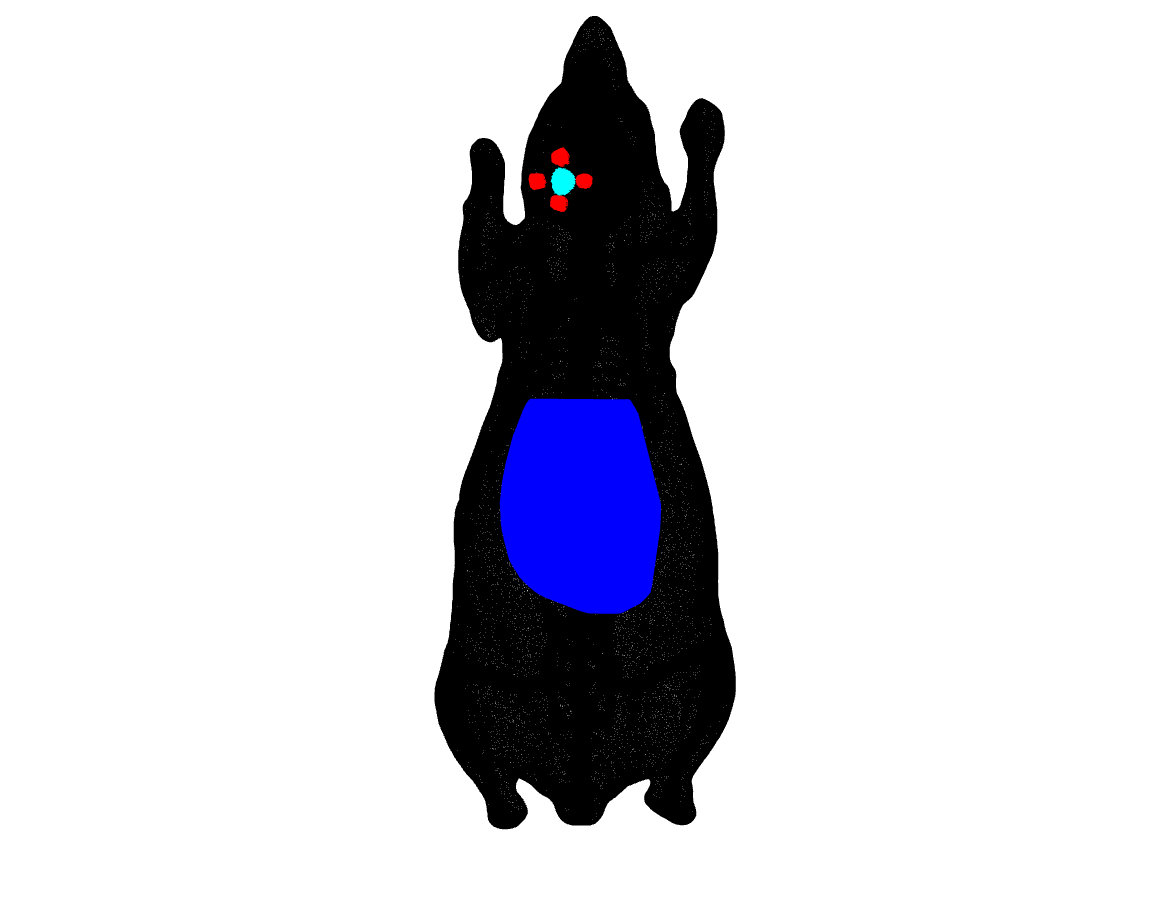

plotMesh(o,tissue="skin")
ylim([-40 40])

This mesh shows the electrodes in red (anode) and blue (cathode). For the craniotomy, the two tissue types that have been removed (skin and bone) are shown in cyan and magenta. 

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in *4x1.mat*), now we export files that the FEM solver GetDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells GetDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...26-Jun-2025 12:43:40
----saveMesh elapsed time: 10.9290 seconds

----Starting savePro...26-Jun-2025 12:43:51
----savePro elapsed time: 0.0156 seconds

Stage EXPORT complete - 8.4171 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 26-Jun-2025 12:43:51 
 ID: 4xBack_craniotomy 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anterior = Region[6];
Posterior = Region[7];
Lateral = Region[8];
Medial = Region[9];
Cathode = Region[10];
leftskin = Region[11];
leftbone = Region[12];
boundaryAnterior = Region[13];
boundaryPosterior = Region[14];
boundaryLateral = Region[15];
boundaryMedial = Region[16];
boundaryCathode = Region[17];
DomainC = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Cathode,leftskin,leftbone}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Cathode,leftskin,leftbone,boundaryAnterior,boundaryPosterior,boundaryLateral,boundaryMedial,boundaryCathode}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anterior] = 0.3;
sigma[Posterio

This file can be opened in the GetDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run GetDP

It will take GetDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in GetDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/Klab/EFMouse/lib/getdp-3.5.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy.msh -pos Map' [GetDP 3.5.0, 1 node, max. 1 thread]
Info    : Started (Thu Jun 26 12:46:02 2025, Wall = 0.00136614s, CPU = 0.0162s, Mem = 4.27734Mb)
Info    : Initializing Gmsh
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                                          
 

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...26-Jun-2025 12:51:31


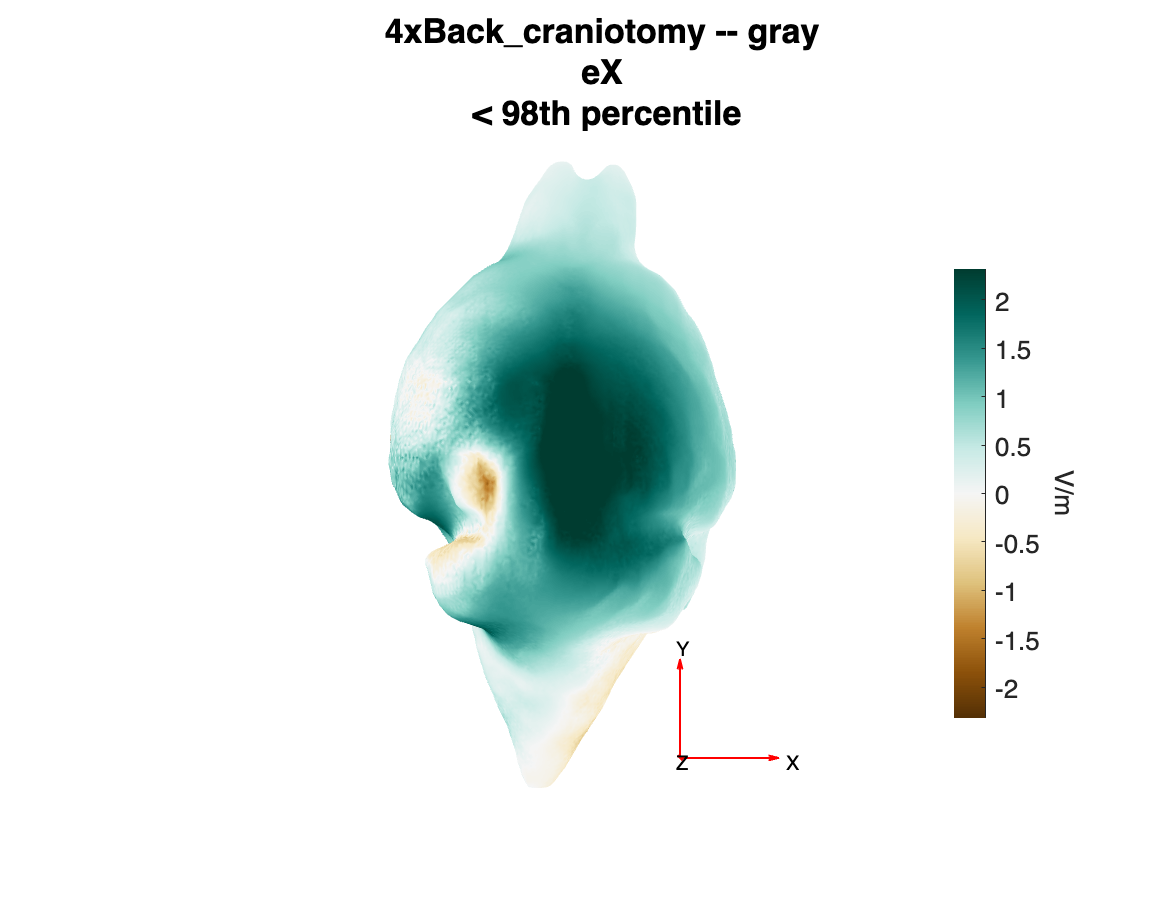

----plotEf elapsed time: 1.9163 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...26-Jun-2025 12:51:33


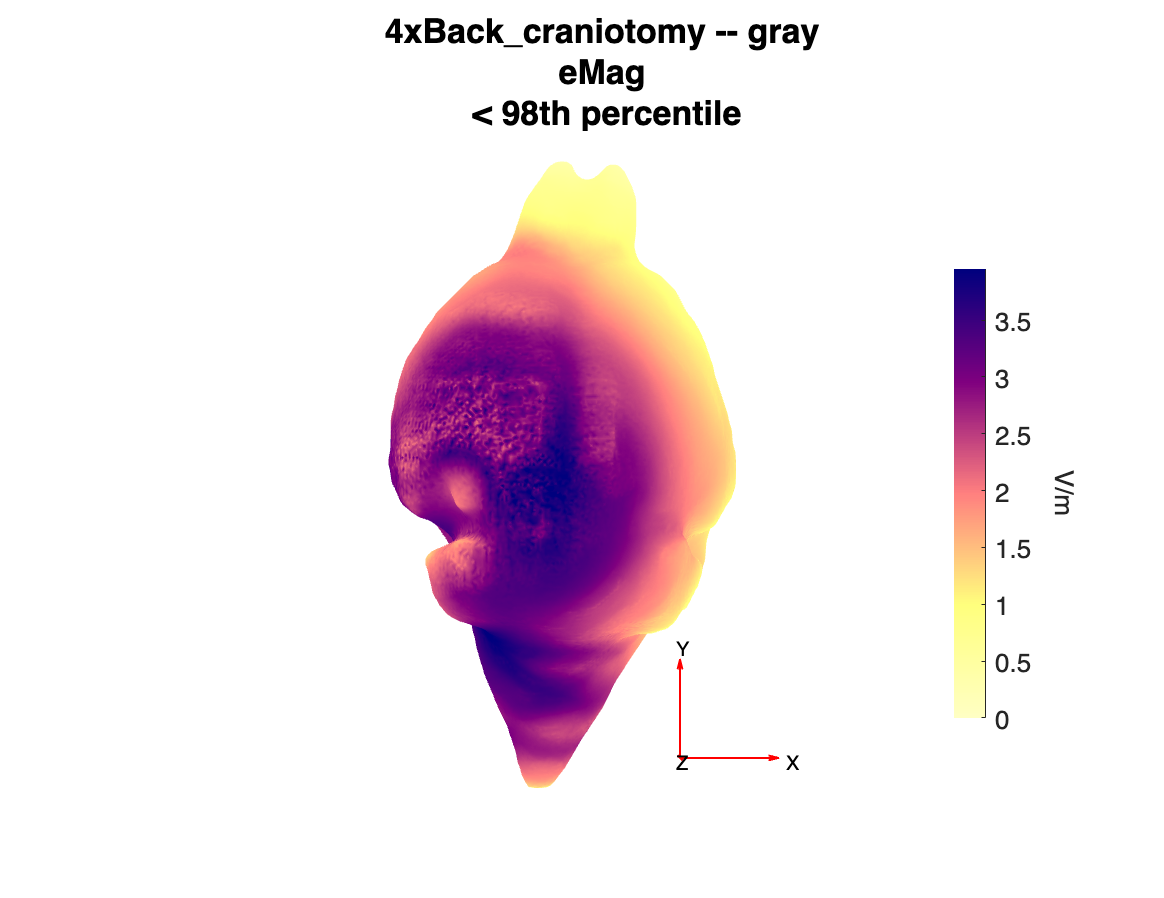

----plotEf elapsed time: 0.8424 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

We can also use `plotEf()` to visualize a brain slice perpendicular to a given axis. Here we show a frontal/coronal plane slice (perpendicular to the y axis) in the position of the anode electrode, a sagittal slice and a horizontal slice.

----Starting plotEf...26-Jun-2025 12:52:14


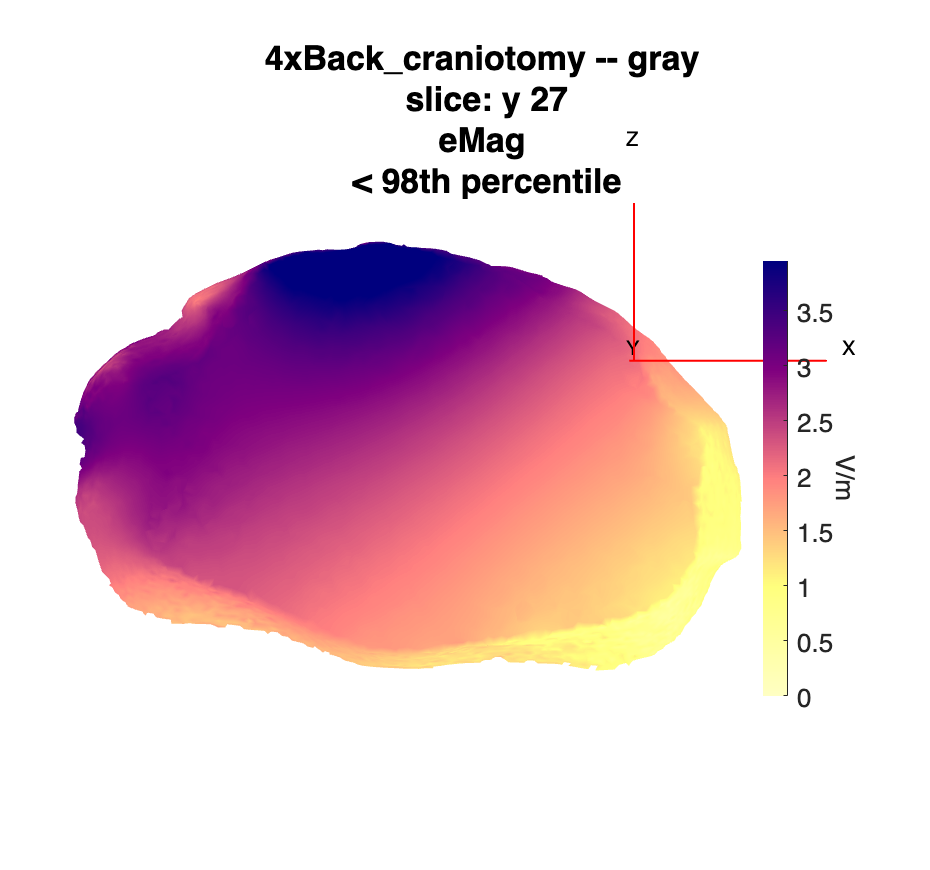

----plotEf elapsed time: 0.6492 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "y",slice_pos = 27)

----Starting plotEf...26-Jun-2025 12:52:14


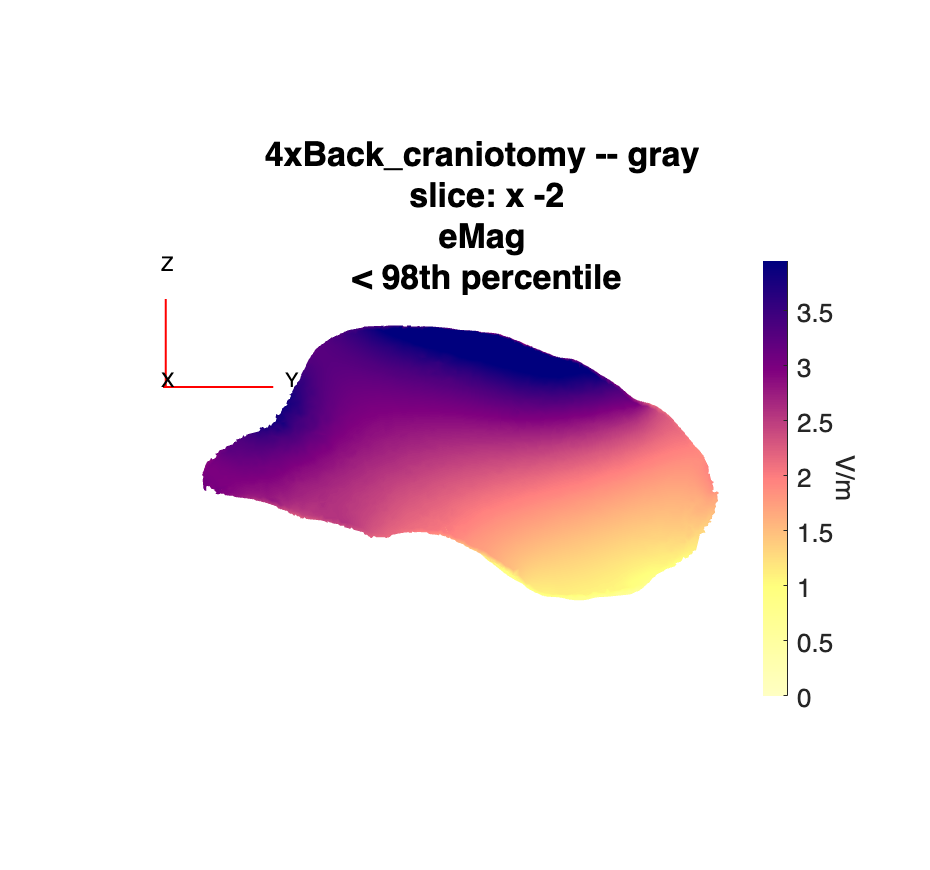

----plotEf elapsed time: 0.5200 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "x",slice_pos = -2)

----Starting plotEf...26-Jun-2025 12:52:15


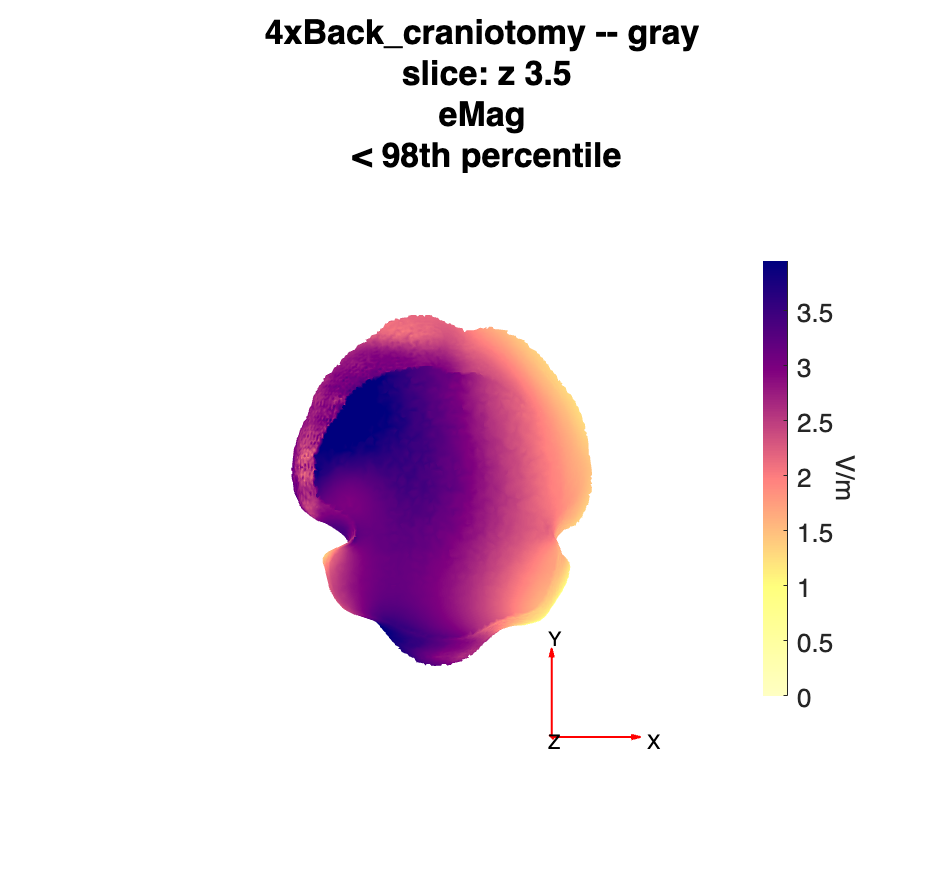

----plotEf elapsed time: 0.4649 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "z",slice_pos = 3.5)

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. `leftbone `refers to the bone area removed during the craniotomy. The label is defined by joining the craniotomy tag (see Stage MESH above) and the tissue removed: `left `+ "bone": `leftbone.`

See Sanchez-Romero et al., (2025) for a full description of the electric field metrics.

summary = analyzeTissue(o,["skin" "gray" "leftbone"]);

----Starting analyzeTissue...26-Jun-2025 12:52:37
Electric field summary statistics for skin tissue
              mean       median       std         min        max  
            ________    _________    ______    _________    ______

    eX       0.26687    0.0037123    2.1745      -58.701    94.208
    eY       -1.0703     -0.57196    2.0397       -103.5    42.073
    eZ      -0.41074     0.025735    4.1325      -154.95    39.544
    eMag      1.8454       1.0583    4.8935    9.483e-07    157.65

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.5926, for ef_norm_mean: (0.051 -0.565 0.170)

Electric field summary statistics for gray tissue
              mean       median       std        min</

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2025), for definitions of relative focality and homogeneity.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  % Left/Right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Inferior/Superior
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=40); % Define values for relative focality metric.

----Starting analyzeRoi...30-Jun-2025 11:56:41
Electric field summary statistics for a box roi in gray
             mean      median       std        min        max  
            _______    _______    _______    _______    _______

    eX       1.4921     1.5027    0.31678    0.20676     2.1213
    eY      -1.4978    -1.5167    0.33052    -2.4748    -0.4516
    eZ      -2.2371     -2.193    0.43778    -3.2671    -0.8974
    eMag     3.1274     3.1122     0.3083     2.0612     3.9181

[Relative focality ranges from 0 to 1]
Relative focality = 0.3490, with 160508 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9836, for ef_norm_mean: (0.475 -0.486 -0.711)


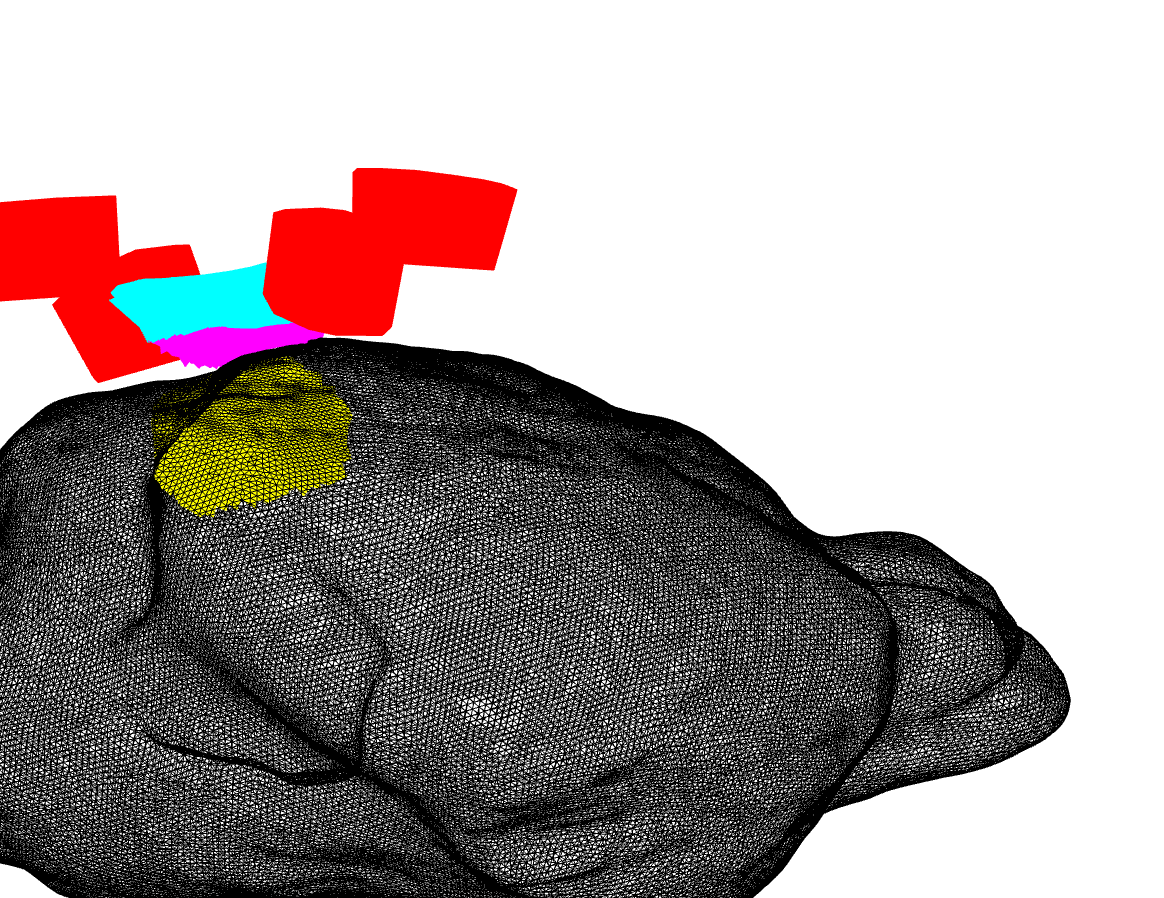

% Rotate and zoom to view the (yellow) box ROI underneath the return electrode
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=40);

----Starting analyzeRoi...30-Jun-2025 11:56:43
Electric field summary statistics for a box roi in gray
              mean       median       std        min        max   
            ________    ________    _______    _______    ________

    eX        1.1156      1.1239    0.18983    0.53849      1.6135
    eY      -0.85333    -0.81839    0.19447    -1.4682    -0.54689
    eZ       -1.0872     -1.0931    0.13861    -1.4245    -0.75071
    eMag      1.7893      1.7888    0.21474     1.2849      2.3458

[Relative focality ranges from 0 to 1]
Relative focality = 0.0897, with 160925 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9927, for ef_norm_mean: (0.623 -0.477 -0.60

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2025), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...26-Jun-2025 12:53:06
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy/4xBack_craniotomy_efZ.nii.gz created
----computeVoxelSpace elapsed time: 9.4329 seconds
Stage ATLAS complete - 17.6427 seconds 


### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 11:59:22
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median       std         min        max  
            _______    _______    _______    _________    ______

    eX      0.83186    0.83146    0.61342      -1.1558    2.0052
    eY      -1.7973    -1.9033    0.54128      -3.0269         0
    eZ      -2.4423    -2.3837    0.98657      -4.5668         0
    eMag     3.2457     3.2792     1.0047    0.0011271     5.098

[Relative focality ranges from 0 to 1]
Relative focality = 0.5117, with 92410 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9641, for ef_norm_mean: (0.247 -0.577 -0.732)
----analy

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 11:59:22
Area: Visual areas (1.0% of brain) , hemisphere right 
             mean      median       std         min        max  
            _______    _______    _______    _________    ______

    eX       1.3851     1.4948    0.61761    0.0018474    2.3576
    eY      -1.0662    -1.1701    0.48817      -2.0097         0
    eZ      -1.1917    -1.2187    0.59796      -2.3548         0
    eMag     2.1477     2.3215    0.91836    0.0026165    3.5328

[Relative focality ranges from 0 to 1]
Relative focality = 0.2236, with 92457 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9849, for ef_norm_mean: (0.645 -0.505 -0.547)
----anal

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy',ID='4xBack_craniotomy')

o = EF Mouse Model (label: 4xBack_craniotomy) in directory /Users/rubensanchez/desktop/efmouse_sim/4xBack_craniotomy (stage=ATLAS).